# **Enfermedad simulada: demencia**

Autor: Juan Parras

Asignatura: SALT

## Descripción del problema

El problema consiste en analizar un modelo simulado muy sencillo de la gravedad de la demencia. Para ello, haremos uso de varias de las herramientas que hemos visto en el temario. Así, vamos a definir las siguientes variables aleatorias:

- $X$: la edad, que es un factor de riesgo, no sólo en la demencia, sino en prácticamente todas las enfermedades (a mayor edad, más probabilidad de que la enfermedad sea grave por el deterioro físico).

- $Y$: el riesgo de padecer problemas vasculares, que es una comorbilidad asociada a la demencia (son dos enfermedades que suelen aparecer juntas).

- $Z$: otros factores de riesgo que no tenemos en el modelo (sexo, condiciones de vida, otras comorbilidades...).

Nuestro objetivo es estudiar la gravedad de la enfermedad, que será una variable aleatoria $W=c\cdot \;X+Y+Z$

## Solución

Comencemos por estudiar los dos factores de riesgo $X$ e $Y$, que vamos a asumir como no independientes. Esto significa que el riesgo de padecer problemas vasculares depende de la edad, lo cual tiene sentido (a más edad, más riesgo). Asumimos que la edad es una variable aleatoria Uniforme $X=U\left\lbrack a,b\right\rbrack$, donde por comodidad fijamos $a=10,\;b=80$ y que $Y=X\cdot \frac{X-k}{8000},k\in \mathbb{R}\;$. Esto significa que $Y$ tiene una relación cuadrática con respecto a $X$, es decir, a mayor edad, mayor riesgo de problemas vasculares. El parámetro $k$ modifica la relación entre ambos factores de riesgo, como se puede ver en la siguiente figura.

a = 10

a = 10

b = 80

b = 80

k = 4.9

k = 4.9000

n_muestras = 1000;
x = random('Uniform', a, b, 1, n_muestras);
y = x .* (x - k) / 8000;
x(1:10)

ans =    67.0307   73.4054   18.8891   73.9363   54.2651   16.8278   29.4949   48.2817   77.0255   77.5422


y(1:10)

ans =     0.5206    0.6286    0.0330    0.6380    0.3349    0.0251    0.0907    0.2618    0.6944    0.7041


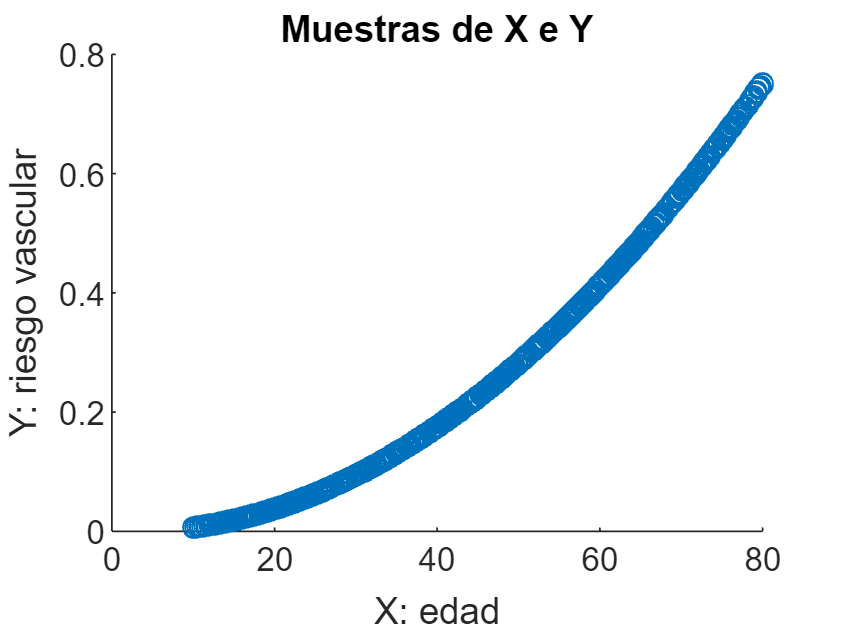


scatter(x, y)
title('Muestras de X e Y')
xlabel('X: edad')
ylabel('Y: riesgo vascular')

Con esta información, podemos calcular los estadísticos de nuestros factores de riesgo. Primero, sabemos que, como $X$ (la edad) es Uniforme, $X\in \left\lbrack a,b\right\rbrack ,{\;\;f}_X \left(x\right)=\frac{1}{b-a}$ y $E\left\lbrack X\right\rbrack =\frac{a+b}{2}$. Calculemos la media de $Y$ empleando la transformación $y=g\left(x\right)=x\cdot \frac{\left(x-k\right)}{8000}$.


$$\begin{array}{l}
E\left\lbrack Y\right\rbrack =E\left\lbrack g\left(X\right)\right\rbrack =\int_a^b g\left(x\right)f_X \left(x\right)\textrm{dx}=\int_a^b \frac{x\cdot \left(x-k\right)}{8000\left(b-a\right)}\textrm{dx}=\frac{1}{8000\left(b-a\right)}\left\lbrack \frac{b^3 -a^3 }{3}-k\cdot \frac{b^2 -a^2 }{2}\right\rbrack \\
=\frac{1}{8000\left(b-a\right)}\left\lbrack \frac{\left(b-a\right)\left(b^2 +a^2 +a\cdot \;b\right)}{3}-k\cdot \frac{\left(b-a\right)\left(b+a\right)}{2}\right\rbrack =\frac{b^2 +a^2 +a\cdot b}{24000}-k\cdot \frac{b+a}{16000}
\end{array}$$


También podemos calcular la Correlación cruzada de $X$ con $Y$:


$$\begin{array}{l}
R_{\textrm{XY}} =E\left\lbrack \textrm{XY}\right\rbrack =E\left\lbrack X\cdot g\left(X\right)\right\rbrack =\int_a^b x\cdot \;g\left(x\right)\cdot \;f_X \left(x\right)\textrm{dx}=\int_a^b \frac{x^2 \cdot \left(x-k\right)}{8000\left(b-a\right)}\textrm{dx}\\
=\frac{1}{8000\left(b-a\right)}\left\lbrack \frac{b^4 -a^4 }{4}-k\cdot \frac{b^3 -a^3 }{3}\right\rbrack =\frac{1}{8000\left(b-a\right)}\left\lbrack \frac{\left(b-a\right)\left(b^3 +a^3 +a\cdot b^2 +a^2 \cdot b\right)}{4}-k\cdot \frac{\left(b-a\right)\left(b^2 +a^2 +a\cdot \;b\right)}{3}\right\rbrack \\
=\frac{b^3 +a^3 +a\cdot b^2 +a^2 \cdot b}{32000}-k\cdot \frac{b^2 +a^2 +a\cdot \;b}{24000}
\end{array}$$


Y con todo esto, podemos calcular la Covarianza cruzada de $X$ con $Y$:


$$\begin{array}{l}
C_{\textrm{XY}} =R_{\textrm{XY}} -E\left\lbrack X\right\rbrack \cdot E\left\lbrack Y\right\rbrack =\frac{1}{8000}\left(\frac{b^3 +a^3 +a\cdot b^2 +a^2 \cdot b}{4}-k\cdot \frac{b^2 +a^2 +a\cdot \;b}{3}-\frac{a+b}{2}\left(\frac{b^2 +a^2 +a\cdot b}{3}-k\cdot \frac{b+a}{2}\right)\right)\\
=\frac{1}{8000}\left(\frac{b^3 +a^3 +a\cdot b^2 +a^2 \cdot b}{4}-k\cdot \frac{b^2 +a^2 +a\cdot \;b}{3}-\frac{a^3 +b^3 +2\cdot \;a\cdot \;\;b^2 +2\cdot \;b\cdot a^2 }{6}+k\cdot \frac{a^2 +b^2 +2\cdot a\cdot b}{4}\right)\\
=\frac{a^3 +b^3 -a\cdot b^2 -a^2 \cdot b-k\cdot \left(a^2 +b^2 -2\cdot a\cdot b\right)}{96000}\;
\end{array}$$


Comprobemos todos estos estadísticos con los datos que hemos generado:

E_x_teoria = (a + b) / 2

E_x_teoria = 45

E_x_empirica = mean(x)

E_x_empirica = 44.2183

E_y_teoria = (b^2 + a^2 + a*b)/24000 - k * (b + a)/16000

E_y_teoria = 0.2766

E_y_empirica = mean(y)

E_y_empirica = 0.2664

E_xy_teoria = (b^3 + a^3 + a*b^2 + a^2*b)/32000 - k * (b^2 + a^2 + a*b) / 24000

E_xy_teoria = 16.7908

E_xy_empirica = mean(x.*y)

E_xy_empirica = 15.9113

C_xy_teoria = (a^3 + b^3 - a*b^2 - a^2 * b - k * (a^2 + b^2 - 2 * a * b)) / 96000

C_xy_teoria = 4.3436

C_xy_empirica = E_xy_empirica - E_x_empirica * E_y_empirica

C_xy_empirica = 4.1310

Sabemos que los factores de riesgo $X$ e $Y$ no son independientes, ya que $Y$ (el riesgo cardiovascular) es función de $X$ (la edad). Sin embargo, sí que pueden ser incorreladas para un valor de $k$:


$$C_{\textrm{XY}} =\frac{a^3 +b^3 -a\cdot b^2 -a^2 \cdot b-k\cdot \left(a^2 +b^2 -2\cdot a\cdot b\right)}{96000}=0\to k=\frac{a^3 +b^3 -a\cdot b^2 -a^2 \cdot b}{a^2 +b^2 -2\cdot a\cdot b}=a+b$$


Comprobémoslo:

k = a + b % k que incorrela X e Y

k = 90

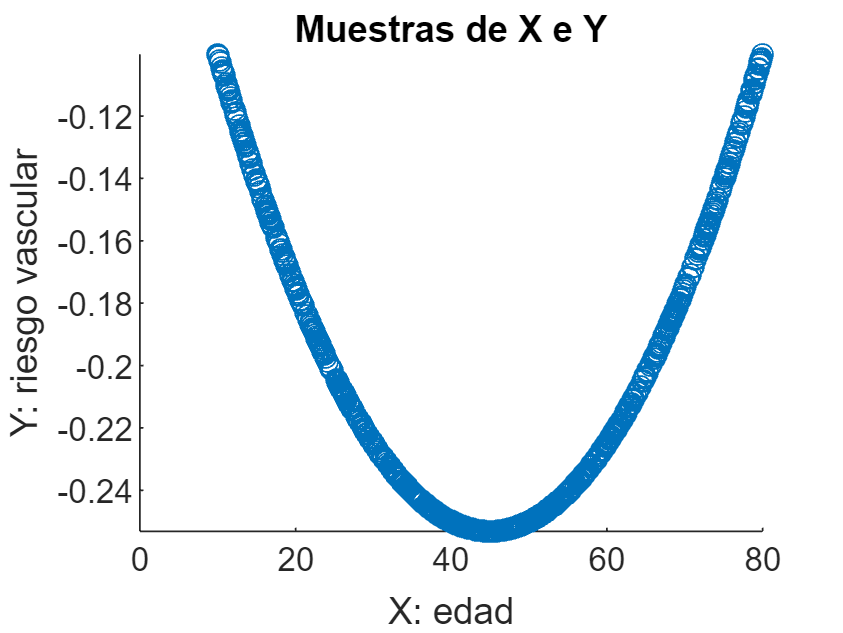

n_muestras = 1000;
x = random('Uniform', a, b, 1, n_muestras);
y = x .* (x - k) / 8000;

scatter(x, y)
title('Muestras de X e Y')
xlabel('X: edad')
ylabel('Y: riesgo vascular')


E_x_teoria = (a + b) / 2

E_x_teoria = 45

E_x_empirica = mean(x)

E_x_empirica = 45.7014

E_y_teoria = (b^2 + a^2 + a*b)/24000 - k * (b + a)/16000

E_y_teoria = -0.2021

E_y_empirica = mean(y)

E_y_empirica = -0.2033

E_xy_teoria = (b^3 + a^3 + a*b^2 + a^2*b)/32000 - k * (b^2 + a^2 + a*b) / 24000

E_xy_teoria = -9.0938

E_xy_empirica = mean(x.*y)

E_xy_empirica = -9.2551

C_xy_teoria = (a^3 + b^3 - a*b^2 - a^2 * b - k * (a^2 + b^2 - 2 * a * b)) / 96000

C_xy_teoria = 0

C_xy_empirica = E_xy_empirica - E_x_empirica * E_y_empirica

C_xy_empirica = 0.0344

Este es un ejemplo importante de que **incorrelación no implica independencia**. Podemos tener dos variables incorreladas que son dependientes, como es este caso. Es importante recordar que la correlación nos da una idea del grado de asociación lineal: en este caso, las variables no tienen una asociación lineal, sino cuadrática. No son independientes, pero sí incorreladas. Notemos que independencia implica que no podemos predecir $Y$ a partir de $X$ de ninguna manera, mientras que incorrelación implica que no podemos predecir $Y$ a partir de $X$ con un modelo lineal.

Pasemos a calcular la gravedad $W=c\cdot \;X+Y+Z$:

- Modelaremos $Z=\mathcal{N}\left(0,0\ldotp 1\right)$, asumiendo que $Z$ es independiente de $X$ (y, por tanto, de $Y$). Estamos asumiendo que la edad es independiente de los factores en $Z$ (lo cual no es realista).

- Asumiremos $c=\frac{1}{80}$ (el factor de normalización de la edad).

- Como $Y$ es una transformación de $X$, podemos expresar los dos primeros sumandos en función de $X$ solamente como:$c\cdot X+Y=\frac{X}{80}+X\cdot \frac{X-k}{8000}=\frac{X^2 +\left(100-k\right)\cdot X}{8000}$

Por tanto, tenemos que la gravedad depende sólo de la edad y de $Z$ como sigue: $W=\frac{X^2 }{8000}+\frac{\left(100-k\right)}{8000}\cdot X+Z$

Por comodidad, en el resto del ejercicio, asumiremos que $k=100$, con lo que $W=\frac{X^2 }{8000}+Z$. Vemos que el primer sumando es una transformación de $X$, que podemos llamar $V=h\left(X\right)=\frac{X^2 }{8000}$, y cuya función de densidad de probabilidad podemos calcular con el Teorema Fundamental:

- 
$$f_X \left(x\right)=\frac{1}{b-a}=\frac{1}{70}$$


- 
$$h^{\prime } \left(x\right)=\frac{x}{4000}$$


- $v=\frac{x^2 }{8000}\to x=\pm \;\sqrt{\;8000\cdot \;v}$, donde tenemos que tener cuidado al tener dos raíces (tendremos dos sumandos al aplicar el Teorema).

Por tanto, $f_V \left(v\right)=\frac{\frac{1}{70}}{\left|\frac{\sqrt{\;8000\cdot v}}{400}\right|}+\frac{\frac{1}{70}}{\left|\frac{-\sqrt{\;8000\cdot v}}{400}\right|}=\frac{8000}{70\cdot 80\sqrt{\;5\cdot v}}=\frac{10}{7\sqrt{\;5\cdot v}},v\in \left\lbrack 0\ldotp 0125,0\ldotp 8\right\rbrack$, como podemos comprobar en la siguiente gráfica:

n_muestras = 1000;
x = random('Uniform', a, b, 1, n_muestras);
v = x.^2 / 8000;
x(1:10)

ans =    62.1407   72.4587   26.9822   19.0718   25.7548   34.5010   30.0959   74.9242   13.5920   51.4867


v(1:10)

ans =     0.4827    0.6563    0.0910    0.0455    0.0829    0.1488    0.1132    0.7017    0.0231    0.3314


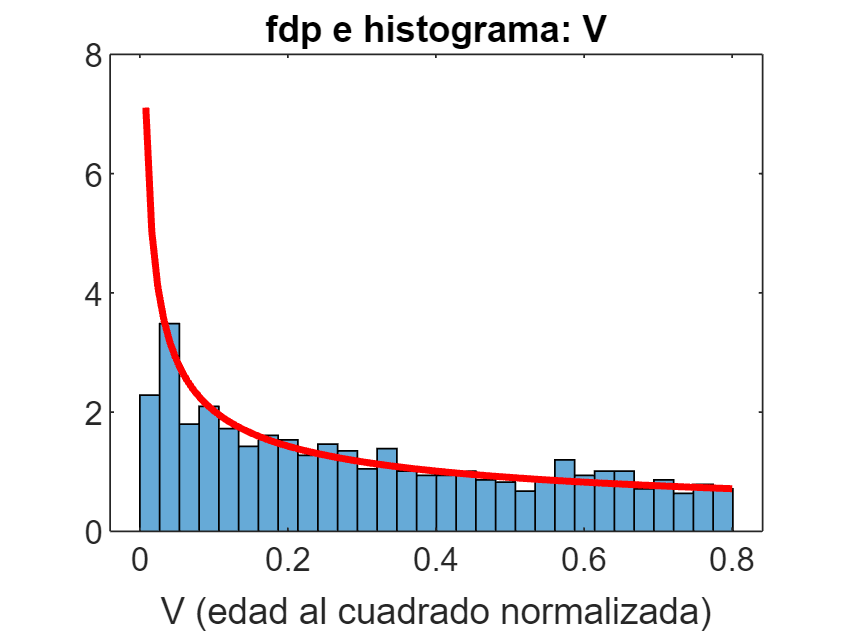


rango = linspace(0, 0.8, 100);
nbins = 30;
histogram(v, nbins, 'Normalization', 'pdf');
hold on;
plot(rango, 10 ./ (7 * sqrt(5 * rango)), 'r', 'LineWidth', 2);
hold off;
title('fdp e histograma: V')
xlabel('V (edad al cuadrado normalizada)')

Antes de pasar a calcular la gravedad, vamos a analizar cómo se distribuyen $V$ y $Z$ (edad al cuadrado y otros factores) mediante un histograma en 2D. Analizando el histograma, se observa que hay regiones con mayor probabilidad de pacientes: las que corresponden a $Z\approx 0$. Esto se debe a que $Z$ es una Gaussiana de media 0, con lo que concentra probabilidad en torno a dicho valor.

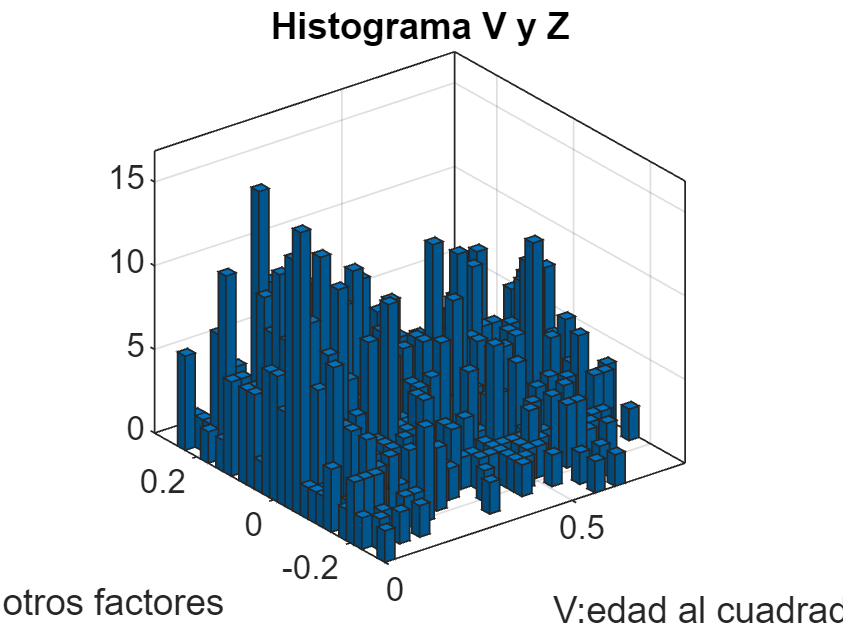

n_muestras = 1000;
x = random('Uniform', a, b, 1, n_muestras);
v = x.^2 / 8000;
z = random('Normal', 0, 0.1, 1, n_muestras);

histogram2(v, z, 30, 'Normalization', 'pdf');
title('Histograma V y Z');
xlabel('V:edad al cuadrado')
ylabel('Z:otros factores')

Pasemos a calcular la función densidad de probabilidad de nuestra gravedad $W=V+Z$, que podemos hacer empleando el Teorema Fundamental. Sin embargo, como $V$ es una transformación de $X$, y $Z$ y $X$ son independientes, sabemos que la función densidad de probabilidad de la suma de dos variables aleatorias independientes es su convolución, por tanto, podemos calcular:


$$f_W \left(w\right)=f_V \left(v\right)*f_Z \left(z\right)$$


Puesto que no es una convolución sencilla analíticamente, la haremos usando las capacidades de cálculo simbólico de MatLAB, y lo comprobaremos usando los datos empíricos:

n_muestras = 1000;
x = random('Uniform', a, b, 1, n_muestras);
v = x.^2 / 8000;
z = random('Normal', 0, 0.1, 1, n_muestras);
w = v + z;
x(1:10)

ans =    32.7702   79.2266   18.6265   61.5114   20.9632   40.4253   68.2570   35.1937   15.3367   48.9848


v(1:10)

ans =     0.1342    0.7846    0.0434    0.4730    0.0549    0.2043    0.5824    0.1548    0.0294    0.2999


z(1:10)

ans =     0.1176    0.0069    0.1726   -0.1450   -0.0285   -0.0874    0.0369   -0.1262   -0.1760   -0.0394


w(1:10)

ans =     0.2518    0.7915    0.2160    0.3280    0.0265    0.1169    0.6192    0.0287   -0.1466    0.2606


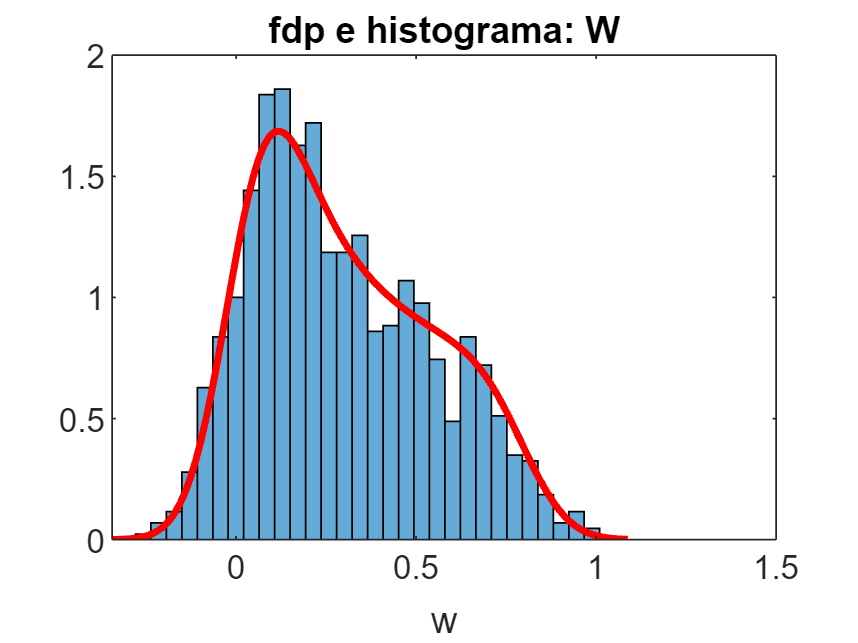


syms t tau  % El cálculo simbólico usa la toolbox symbolic math: se puede añadir con el menú de add-ons
fv(tau) = 10 ./ (7 * sqrt(5 * tau)) * heaviside(tau - 0.0125) * (1 - heaviside(tau - 0.8)); % La fdp de V
fz(tau) = exp(-tau^2/(2*0.1^2)) / (sqrt(2 * pi) * 0.1);  % La fdp de Z (gaussiana)
fw = int(fv(tau)*fz(t-tau),'tau',-Inf,+Inf); % Esta es la integral de la convolución

rango = linspace(min(w) - 0.1, max(w) + 0.1, 100);
t = rango;
fw_num = subs(fw);  % Aquí evaluamos la integral, esto puede tardar un poco

nbins = 30;
histogram(w, nbins, 'Normalization', 'pdf');
hold on;
plot(rango, fw_num, 'r', 'LineWidth', 2);
hold off;
title('fdp e histograma: W')
xlabel('w')

Como se puede comprobar, la variable aleatoria $W$ toma valores positivos y negativos, y tiene una distribución que no se corresponde con ninguna distribución de las que hemos visto en el temario.

Vamos a visualizar, mediante un diagrama de dispersión, cómo afectan los valores de $X$ y $Z$ a $W$: podemos ver que, mientras más grande es la edad ($X$) y los efectos no controlados ($Z$), mayor es la gravedad ($W$).

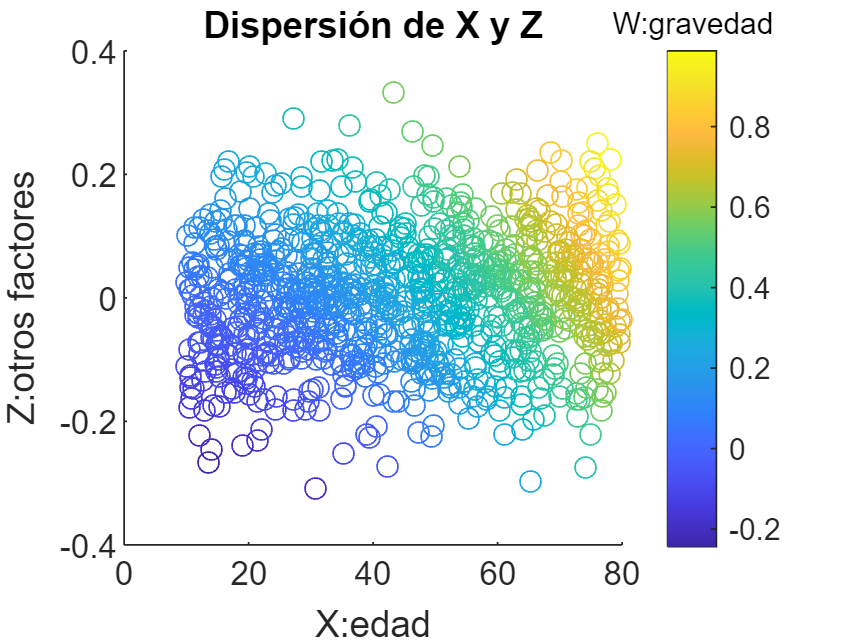

scatter(x, z, [], w);
hcb=colorbar;
title(hcb,'W:gravedad')
title('Dispersión de X y Z')
xlabel('X:edad')
ylabel('Z:otros factores')